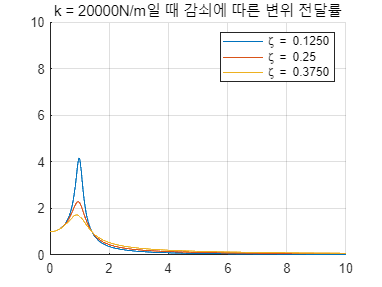

% © 2022 2018100778 최동욱 기계공학과 <ch3044637@khu.ac.kr>
% 2022-1학기 기계진동 term_project
% 0~160km/h 속도범위에서 자동차의 진동분석

clear; clc;

% m = 800
m = 800;

% initial condition
k = [2e4 4e4 8e4];
c = [1e3 2e3 3e3];
v = 0:0.1:160;
l = 0.005; hour2sec = 3600;

% natural frequency, driving frequency, frequency ratio, damping ratio
Wn = sqrt(k/m);
Wb = v*2*pi/(l*hour2sec);
for i = 1:3
    r(i,:) = Wb/Wn(i);
end
zeta = [c/(2*sqrt(m*k(1))); c/(2*sqrt(m*k(2))); c/(2*sqrt(m*k(3)))];

% displacement transmissibility
for i = 1:3
    for j = 1:3
        XperY(3*(i-1)+j,:) = sqrt((1+(2*zeta(i,j)*r(i,:)).^2)./((1-r(i,:).^2).^2+(2*zeta(i,j)*r(i,:)).^2));
    end
end

% plot
hold on
for i = 1:3
    plot(r(1,:), XperY(i,:));
    grid on;
end
title('k = 20000N/m일 때 감쇠에 따른 변위 전달률');
legend( '\zeta = 0.1250', '\zeta = 0.25', '\zeta = 0.3750');
axis([0,10,0,10]);
hold off

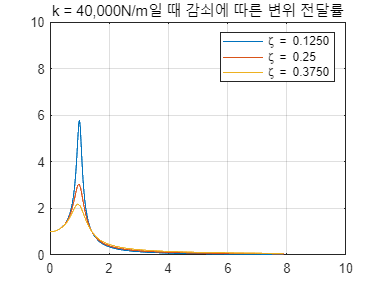


plot(r(2,:), XperY(4,:));
hold on;
for i = 5:6
    plot(r(2,:), XperY(i,:));
    grid on;
end
title('k = 40,000N/m일 때 감쇠에 따른 변위 전달률');
legend( '\zeta = 0.1250', '\zeta = 0.25', '\zeta = 0.3750');
axis([0,10,0,10]);
hold off;

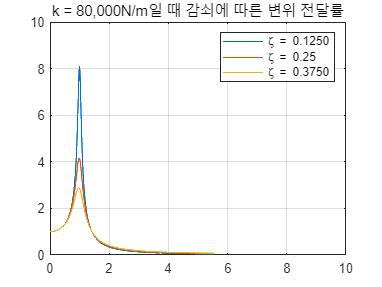


plot(r(3,:), XperY(7,:));
hold on;
for i = 8:9
    plot(r(3,:), XperY(i,:));
    hold on;
    grid on;
end
title('k = 80,000N/m일 때 감쇠에 따른 변위 전달률');
legend( '\zeta = 0.1250', '\zeta = 0.25', '\zeta = 0.3750');
axis([0,10,0,10]);
hold off;

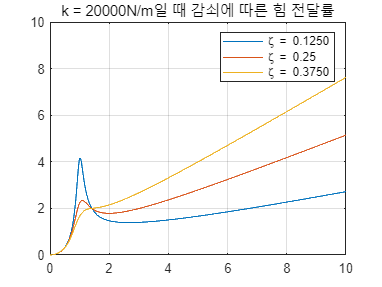


% force transmissibility
for i = 1:3
    for j = 1:3
        FtperkY(3*(i-1)+j,:) = r(i,:).^2.*sqrt((1+(2*zeta(i,j)*r(i,:)).^2)./((1-r(i,:).^2).^2+(2*zeta(i,j)*r(i,:)).^2));
    end
end

% plot
plot(r(1,:), FtperkY(1,:));
hold on
for i = 2:3
    plot(r(1,:), FtperkY(i,:));
    grid on;
end
title('k = 20000N/m일 때 감쇠에 따른 힘 전달률');
legend( '\zeta = 0.1250', '\zeta = 0.25', '\zeta = 0.3750');
axis([0,10,0,10]);
hold off

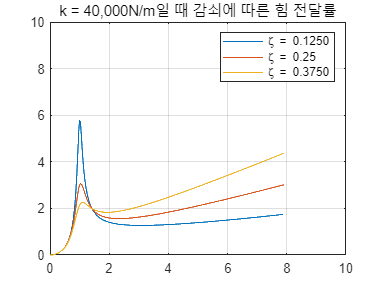


plot(r(2,:), FtperkY(4,:));
hold on;
for i = 5:6
    plot(r(2,:), FtperkY(i,:));
    grid on;
end
title('k = 40,000N/m일 때 감쇠에 따른 힘 전달률');
legend( '\zeta = 0.1250', '\zeta = 0.25', '\zeta = 0.3750');
axis([0,10,0,10]);
hold off;

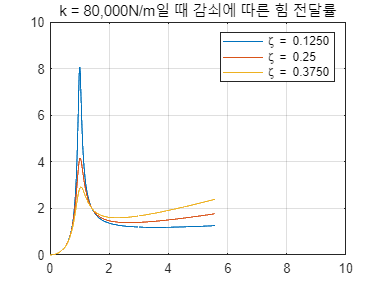


plot(r(3,:), FtperkY(7,:));
hold on;
for i = 8:9
    plot(r(3,:), FtperkY(i,:));
    hold on;
    grid on;
end
title('k = 80,000N/m일 때 감쇠에 따른 힘 전달률');
legend( '\zeta = 0.1250', '\zeta = 0.25', '\zeta = 0.3750');
axis([0,10,0,10]);
hold off;

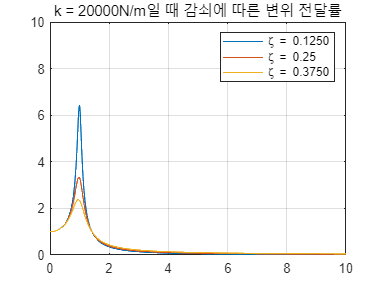


% m = 2000
m = 2000;

% initial condition
k = [2e4 4e4 8e4];
c = [1e3 2e3 3e3];
v = 0:0.1:160;
l = 0.005; hour2sec = 3600;

% natural frequency, driving frequency, frequency ratio, damping ratio
Wn = sqrt(k/m);
Wb = v*2*pi/(l*hour2sec);
for i = 1:3
    r(i,:) = Wb/Wn(i);
end
zeta = [c/(2*sqrt(m*k(1))); c/(2*sqrt(m*k(2))); c/(2*sqrt(m*k(3)))];

% displacement transmissibility
for i = 1:3
    for j = 1:3
        XperY(3*(i-1)+j,:) = sqrt((1+(2*zeta(i,j)*r(i,:)).^2)./((1-r(i,:).^2).^2+(2*zeta(i,j)*r(i,:)).^2));
    end
end

% plot
    plot(r(1,:), XperY(1,:));
hold on
for i = 2:3
    plot(r(1,:), XperY(i,:));
    grid on;
end
title('k = 20000N/m일 때 감쇠에 따른 변위 전달률');
legend( '\zeta = 0.1250', '\zeta = 0.25', '\zeta = 0.3750');
axis([0,10,0,10]);
hold off

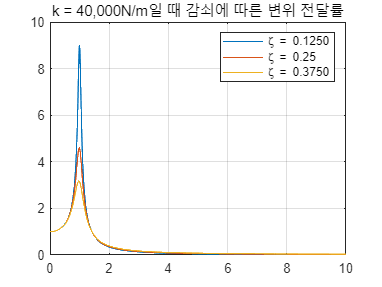


plot(r(2,:), XperY(4,:));
hold on;
for i = 5:6
    plot(r(2,:), XperY(i,:));
    grid on;
end
title('k = 40,000N/m일 때 감쇠에 따른 변위 전달률');
legend( '\zeta = 0.1250', '\zeta = 0.25', '\zeta = 0.3750');
axis([0,10,0,10]);
hold off;

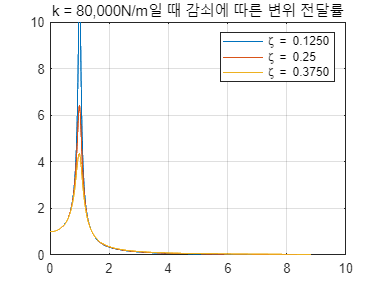


plot(r(3,:), XperY(7,:));
hold on;
for i = 8:9
    plot(r(3,:), XperY(i,:));
    hold on;
    grid on;
end
title('k = 80,000N/m일 때 감쇠에 따른 변위 전달률');
legend( '\zeta = 0.1250', '\zeta = 0.25', '\zeta = 0.3750');
axis([0,10,0,10]);
hold off;

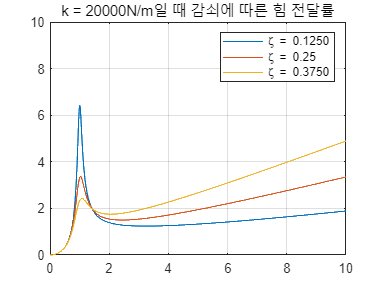


% force transmissibility
for i = 1:3
    for j = 1:3
        FtperkY(3*(i-1)+j,:) = r(i,:).^2.*sqrt((1+(2*zeta(i,j)*r(i,:)).^2)./((1-r(i,:).^2).^2+(2*zeta(i,j)*r(i,:)).^2));
    end
end

% plot
plot(r(1,:), FtperkY(1,:));
hold on
for i = 2:3
    plot(r(1,:), FtperkY(i,:));
    grid on;
end
title('k = 20000N/m일 때 감쇠에 따른 힘 전달률');
legend( '\zeta = 0.1250', '\zeta = 0.25', '\zeta = 0.3750');
axis([0,10,0,10]);
hold off

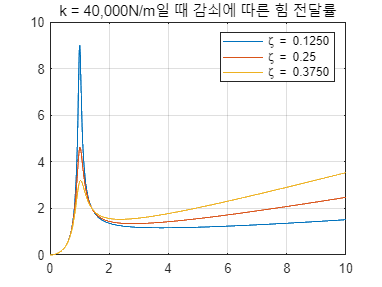


plot(r(2,:), FtperkY(4,:));
hold on;
for i = 5:6
    plot(r(2,:), FtperkY(i,:));
    grid on;
end
title('k = 40,000N/m일 때 감쇠에 따른 힘 전달률');
legend( '\zeta = 0.1250', '\zeta = 0.25', '\zeta = 0.3750');
axis([0,10,0,10]);
hold off;

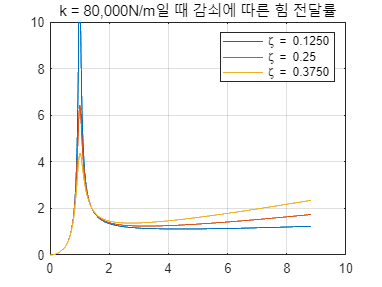


plot(r(3,:), FtperkY(7,:));
hold on;
for i = 8:9
    plot(r(3,:), FtperkY(i,:));
    hold on;
    grid on;
end
title('k = 80,000N/m일 때 감쇠에 따른 힘 전달률');
legend( '\zeta = 0.1250', '\zeta = 0.25', '\zeta = 0.3750');
axis([0,10,0,10]);
hold off;